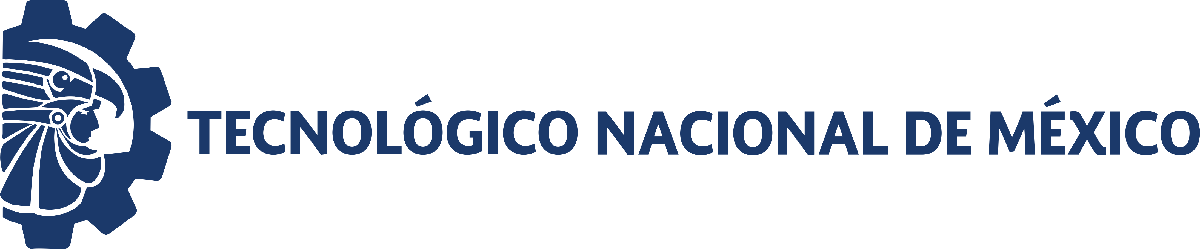                                 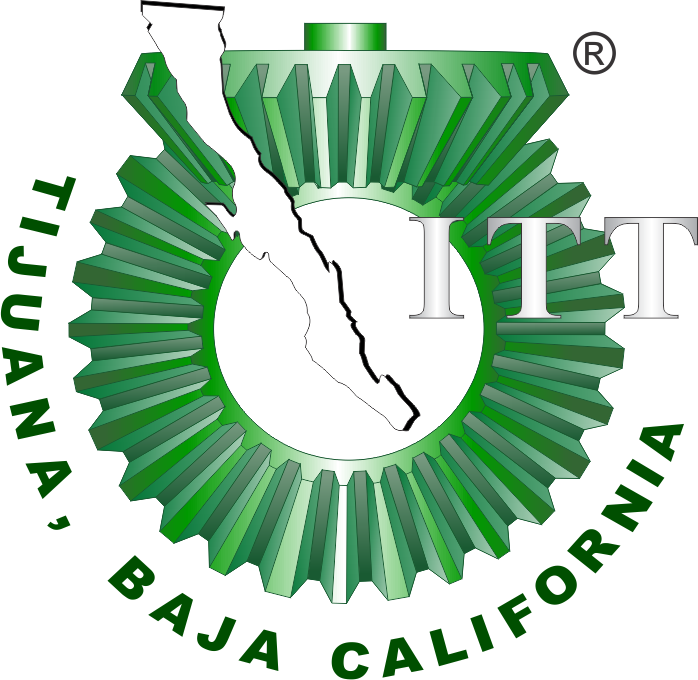

# Práctica 4: Sistema Endocrino  

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información                                                           

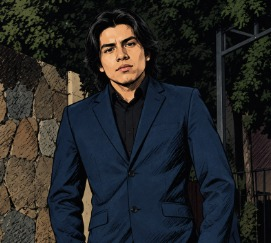

Nombre del alumno: **David Esau Cerano Fuentes**

Número de control: **23210696**

Correo institucional: **L23210696@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
file = 'Cerano23210696Pr4';
open_system(file);
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
x = sim(file,parameters);

## Respuesta impulso unitario 

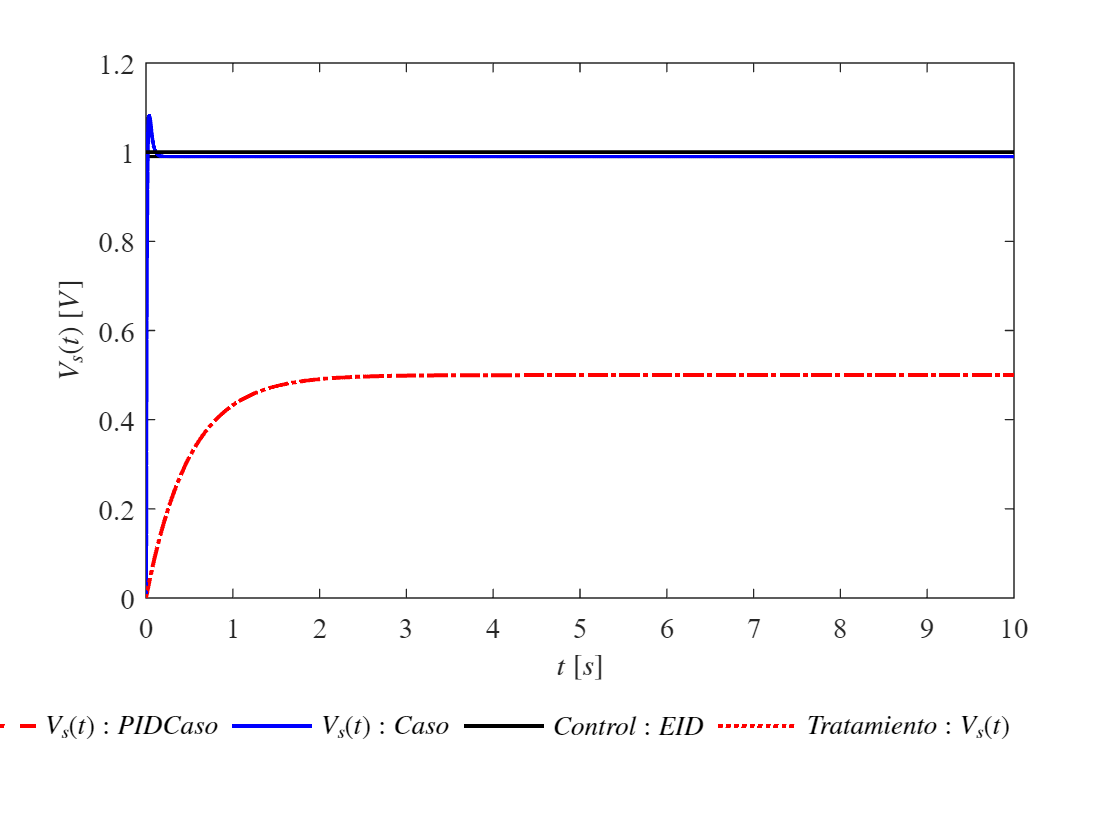

plotsignals(x.t, x.Ve, x.Control, x.Caso, x.PID, x.Control1)

## Funcion: Respuesta de la simulacion 

function plotsignals(t, Ve, Control, Caso, PID,Control1)
    fig = figure();
    set(fig, 'Color', 'w')
    set(gca, 'Units', 'centimeters', 'Position', [2, 3, 22, 16])

    mycolors = [0.00, 0.00, 0.00; 
                1.00, 0.00, 0.00; 
                0.00, 0.00, 1.00];
    
    colororder(mycolors)

    subplot(1, 1, 1);
    box on; hold on;
    
    plot(t, Control, '-', t, Caso, '--', t, PID, '-', t, Ve,'-',t, Control1,':','LineWidth', 1.5);
    
    L = legend('$V_e(t)$','$V_s(t):PID Caso$', '$V_s(t): Caso$','$Control: EID$', '$Tratamiento: V_s(t)$');
    
    set(L, 'Interpreter', 'Latex', ...
           'FontSize', 10, ...
           'FontName', 'Arial', ...
           'Location', 'southoutside', ...
           'Box', 'off', ...
           'Orientation', 'horizontal');

    set(gca, 'FontName', 'Time new roman', 'FontSize', 11)

    xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11)
    ylabel('$V_s(t)$ $[V]$', 'Interpreter', 'Latex', 'FontSize', 11)
    
    xlim([0, 10]); xticks(0:1:10);
    ylim([0, 1.2]); yticks(0:0.2:1.2);
    

    exportgraphics(gcf, 'endocrinomath.pdf', 'ContentType', 'vector')
end